clear all
close all
clc

load('Benchmark_EEG_medium')
load('Benchmark_EEG_small')

PAR = size(EEGdata,1);          % #participants 
REA = size(EEGdata{2}.angle,1); % #realizations

rng(1);

Preprocessing Data

ds = 8

ds = 8


for i = 1:PAR
    for j = 1:REA
out = squeeze(EEGdata{i}.comp(j,:,:))';
in  = squeeze(EEGdata{i}.angle(j,:,:))';

outlierz = isoutlier(mean(out)) | isoutlier(var(out));

out=smoothdata(out(:,~outlierz),'gaussian',4*ds);
in=smoothdata(in(:,~outlierz),'gaussian',4*ds);

outbounds = (max(abs(out))<4);

EEGclean{i}.out{j}=out(1:ds:end,outbounds)/8+0.5;
EEGclean{i}.in{j}=in(1:ds:end,outbounds)/0.12+0.5;
    end
end



% average over periods and downsample, see Section II-B of paper
for Sidx=1:PAR
    smalldata.u(Sidx,:,:)=squeeze(mean(EEGdata{Sidx}.angle(:,:,1:ds:end),2)/0.12+0.5);
    smalldata.y(Sidx,:,:)=squeeze(mean(EEGdata{Sidx}.comp(:,:,1:ds:end),2))/8+0.5;
end

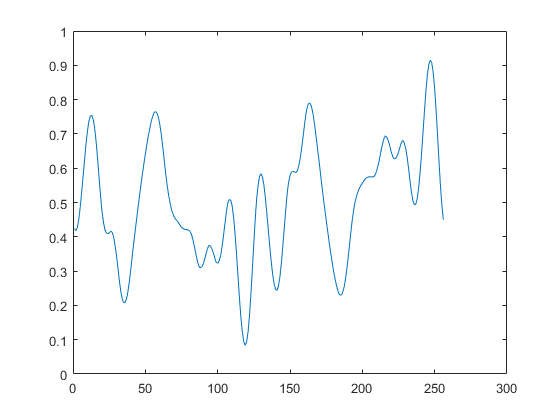


plot(squeeze(smalldata.u(1,1,:)))

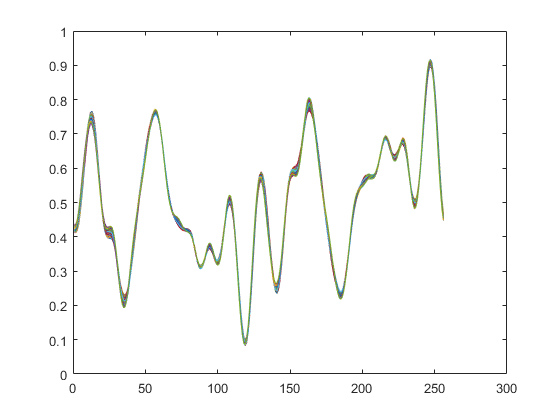

plot(EEGclean{1}.in{1})

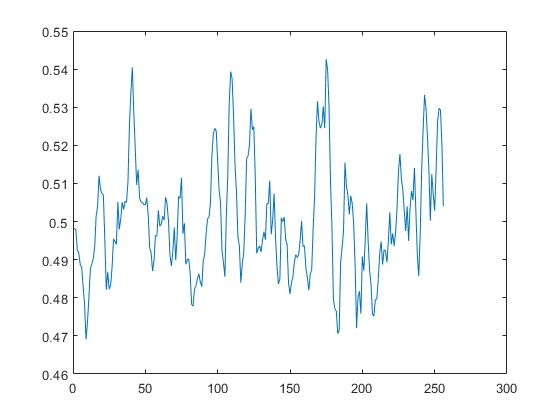


plot(squeeze(smalldata.y(1,1,:)))

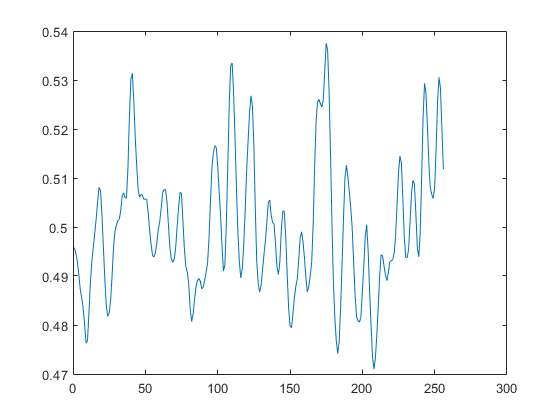

plot(mean(EEGclean{1}.out{1}(:,:)'))


var(squeeze(smalldata.y(1,1,:)))

ans = 2.2485e-04

var(mean(EEGclean{1}.out{1}(:,:)'))

ans = 1.9008e-04

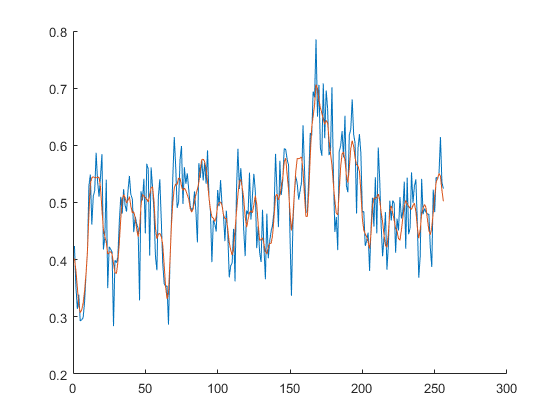


figure;
hold on
plot(squeeze((EEGdata{1}.comp(1,1,1:ds:end))/8+0.5))
plot((EEGclean{1}.out{1}(:,1)))
hold off


FY = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,1,1:1:end))))/8+0.5)));
FYY = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,1,1:ds:end))))/8+0.5)));
FZ = mag2db(abs(fft(((EEGclean{1}.out{1}(:,1))))));
FX = mag2db(abs(fft((squeeze(smalldata.y(1,1,:))))))

FX =    42.1465
  -13.7999
   -8.1543
  -35.6674
    2.9308
  -14.9364
  -10.1326
   -5.9869
   -8.4546
  -13.4704


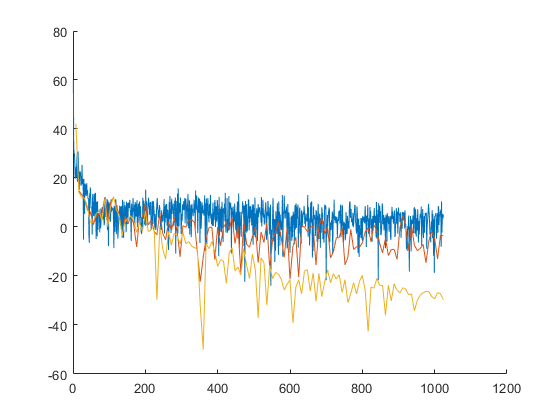


figure;
hold on
plot(FY(1:floor(end/2)))
plot(8:ds:1024,FYY(1:floor(end/2)))
plot(8:ds:1024,FZ(1:floor(end/2)))
% plot(8:ds:1024,FX(1:floor(end/2)))
hold off

partici = 1 

partici = 1


input = [];
output = [];
    for j = 1:REA
input = [EEGclean{partici}.in{j} input];
output = [EEGclean{partici}.out{j} output];
    end
    
tinput = squeeze(smalldata.u(partici,:,:))';
toutput = squeeze(smalldata.y(partici,:,:))';

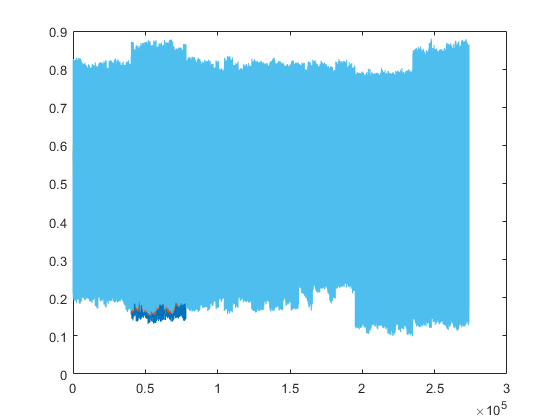

inlags=[6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-201:end-inlags(l)-1,:), [],1));
end

vlags=[10 9 8 6 5 4];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-201:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-200:end-vlags(l),:), [],1))/0.2+0.5;
end

plot(v)

outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-200:end-outlags(l),:), [],1);
end



testind = [20000:20200 60000:60200 10000:10200 130000:130200 170000:170200 200000:200200 240000:240200];
trainind = setdiff([1:size(u,1)],testind);

featurez = [u(trainind,:) v(trainind,:) y(trainind,2:end)];
zeta = y(trainind,1);

tfeaturez = [u(testind,:) v(testind,:) y(testind,2:end)];
yt = y(testind,1);

% tfeaturez = featurez(1:400,:);
% yt = zeta(1:400,:);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                 %degree B-spline
m = 4;                  %Number of knot intervals
In = n+m;

un = basisvectors(featurez,n,m);



Initialize tensor train

% Choose TT-ranks
maxrank = 10;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank))

r =      1     6    10    10    10    10    10    10    10    10    10    10    10     6     1



[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 8.6672e-08


Optimize TT cores

lambda=10^-4

lambda = 1.0000e-04

difforder=2;
MAXITR = d;
nselect = floor(logspace(log10(dof*2/N),0,MAXITR)*0.5*N);
% plot(nselect);

[TN,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder)

    "iteration:"    "2"    "1.8162"

    "iteration:"    "3"    "3.6427"

    "iteration:"    "4"    "5.613"

    "iteration:"    "5"    "7.7819"

    "iteration:"    "6"    "10.1206"

    "iteration:"    "7"    "12.7331"

    "iteration:"    "8"    "15.7125"

    "iteration:"    "9"    "19.1456"

    "iteration:"    "10"    "23.0678"

    "iteration:"    "11"    "27.6534"

    "iteration:"    "12"    "33.0413"

    "iteration:"    "13"    "39.4976"

    "iteration:"    "14"    "47.3745"



TN = struct with fields:
    core: {[1×6×6 double]  [6×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×10 double]  [10×6×6 double]  [6×6 double]}
      sz: [14×3 double]


res1 =     0.0020    0.0005    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


res2 = 	1.0e+04 *

    0.3533    1.4067    0.1651    0.5358    0.2389    0.5593    0.4195    0.7194    0.6577    1.1417    0.9494    1.6347    1.5746


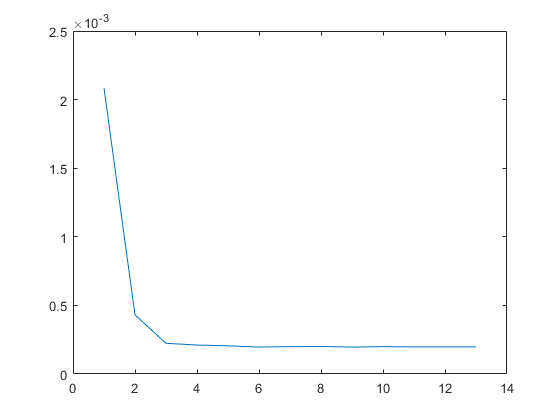

plot(res1)

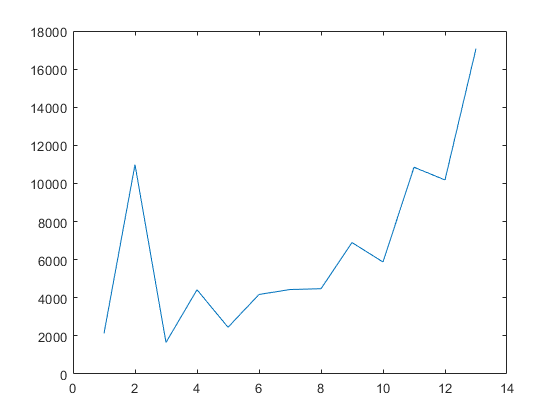

plot(res2)

Evaluate Test data

yhat = evalspline(TN,tfeaturez,n,m);


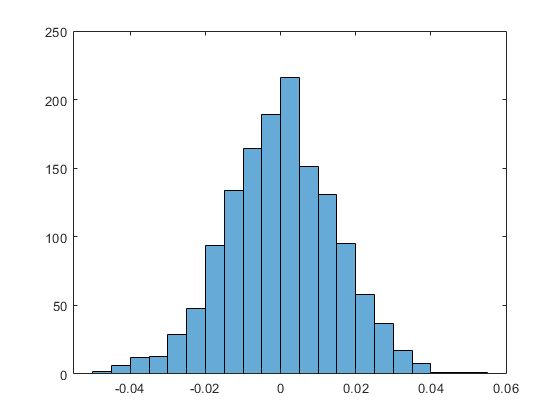

erboi = (yhat-yt);
histogram((erboi)');

VAF = 1-var(erboi)/var(yt)

VAF = 0.9766

MSE = immse(yhat,yt)

MSE = 2.1653e-04

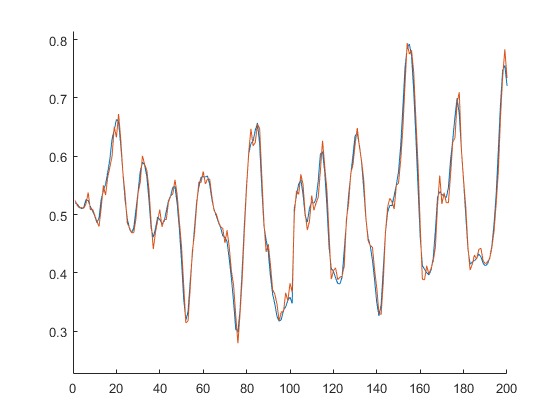


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 200 -inf inf])

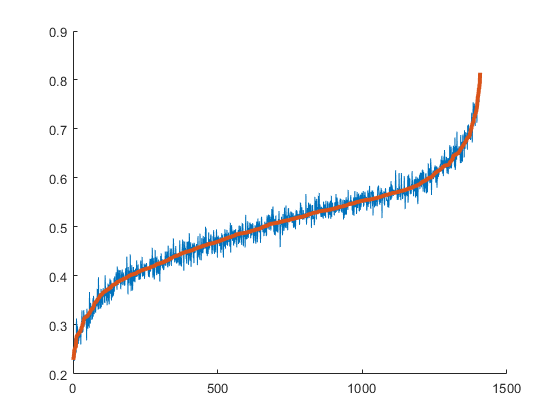


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

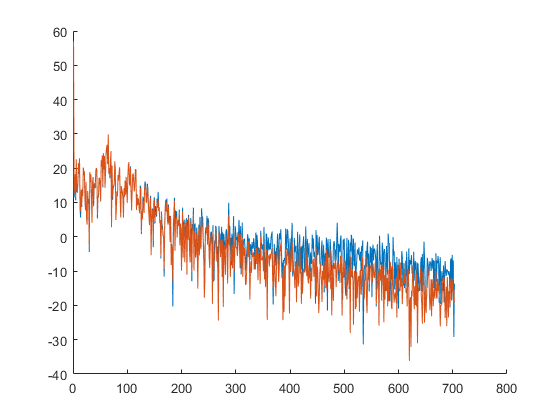


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FY(1:floor(end/2)))
plot(FZ(1:floor(end/2)))
hold off